startup_rtb

- Robotics Toolbox for MATLAB (release 10.3)
 - ARTE contributed code: 3D models for robot manipulators (C:\Users\Robert\Documents\MATLAB\Add-Ons\Toolboxes\Robotics Toolbox for MATLAB\code\robot\data\ARTE)
 - pHRIWARE (release 1.1): pHRIWARE is Copyrighted by Bryan Moutrie (2013-2018) (c)


clear; clc;

## Define rotation

2D Rotation matrix rotating 0 rad

rot2(0)

ans =      1     0
     0     1



% 2D Rotation matrix rotating 0.2 rad
 rot2(0.2)

ans =     0.9801   -0.1987
    0.1987    0.9801


 
% 2D Rotation matrix rotating 30 degrees and store it in R
 R = rot2(30, 'deg')

R =     0.8660   -0.5000
    0.5000    0.8660


## Rotation matrix properties

Verify orthogonality of the columns

c1 = R(:,1); c2 = R(:,2);
dot(c1,c2)

ans = 0


% Verify determinant equal to 1
det(R)

ans = 1


% Verify that the inverse is equal to the transpose
inv(R)

ans =     0.8660    0.5000
   -0.5000    0.8660



R'

ans =     0.8660    0.5000
   -0.5000    0.8660



inv(R)-R'

ans =    1.0e-16 *

         0   -0.5551
    0.5551         0


## Visualize the rotation matrix as a rotation of the coordinate frame

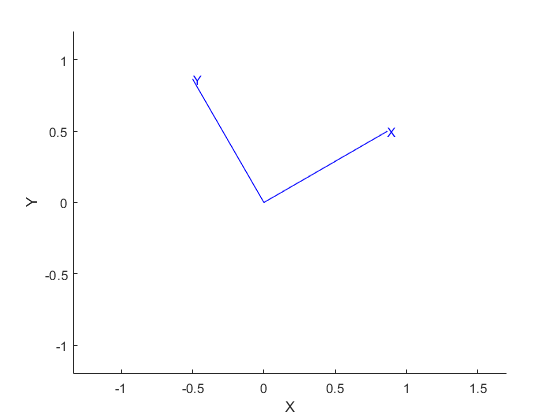

trplot2(R)
axis equal